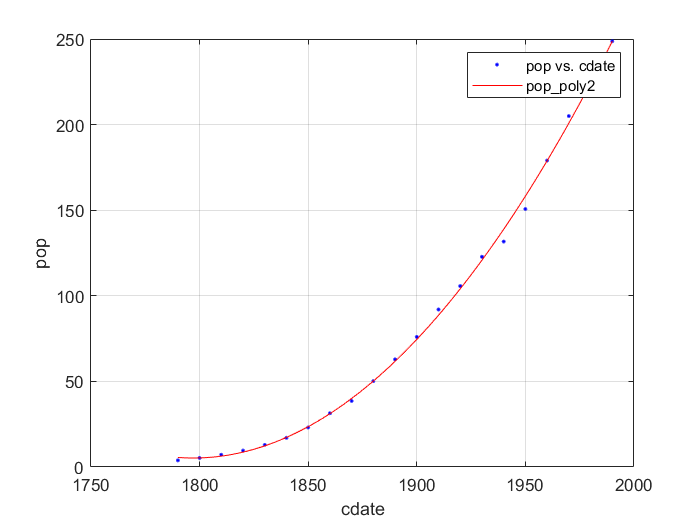

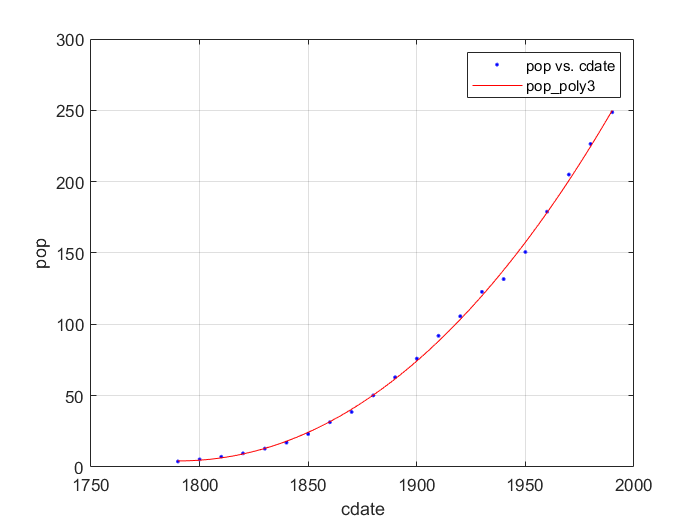

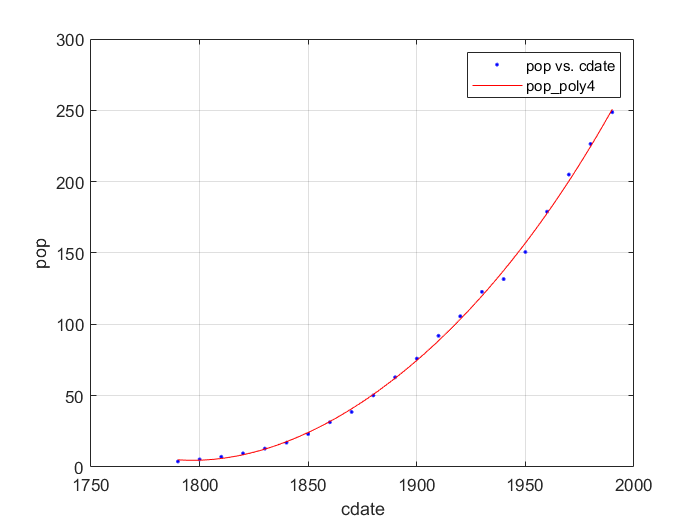

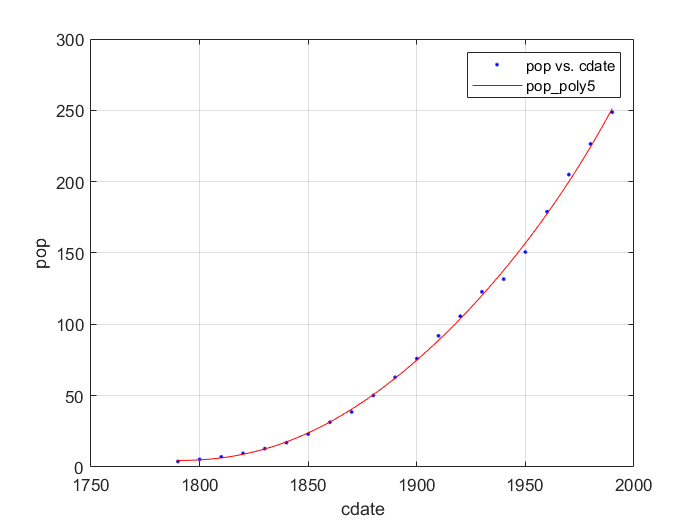

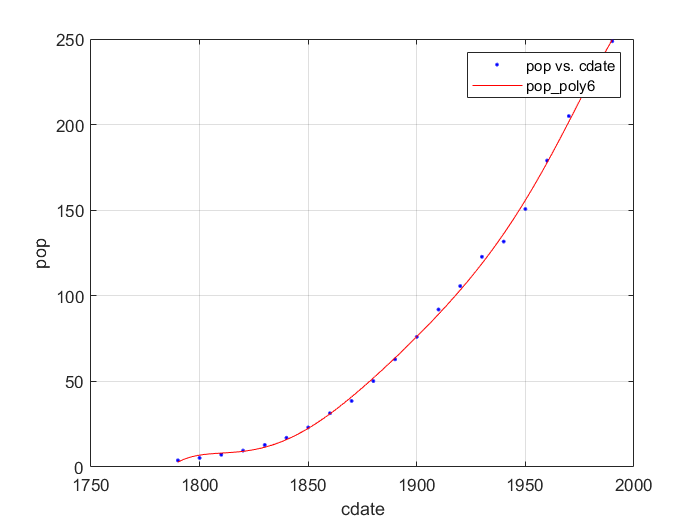

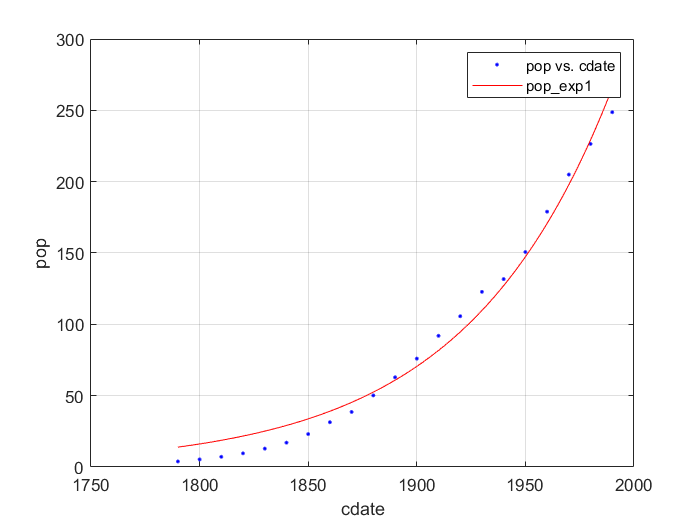

fitresult = 6×1 cell array
    {1×1 cfit}
    {1×1 cfit}
    {1×1 cfit}
    {1×1 cfit}
    {1×1 cfit}
    {1×1 cfit}


gof = 6×1 struct array with fields:
    sse
    rsquare
    dfe
    adjrsquare
    rmse


clear all
close all
load datiOhm.mat
load census.mat
%cftool ese_cftool.sfit
%[fitresult, gof] = createFits(cdate, pop)

clear all
close all
load datiOhm.mat
[curvefit,gof,output]=fit(I',V','poly1')

curvefit =      Linear model Poly1:
     curvefit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       0.137  (0.1221, 0.1519)
       p2 =      0.1544  (-0.2985, 0.6073)

gof = struct with fields:
           sse: 1.2955
       rsquare: 0.9739
           dfe: 11
    adjrsquare: 0.9716
          rmse: 0.3432


output = struct with fields:
        numobs: 13
      numparam: 2
     residuals: [13×1 double]
      Jacobian: [13×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


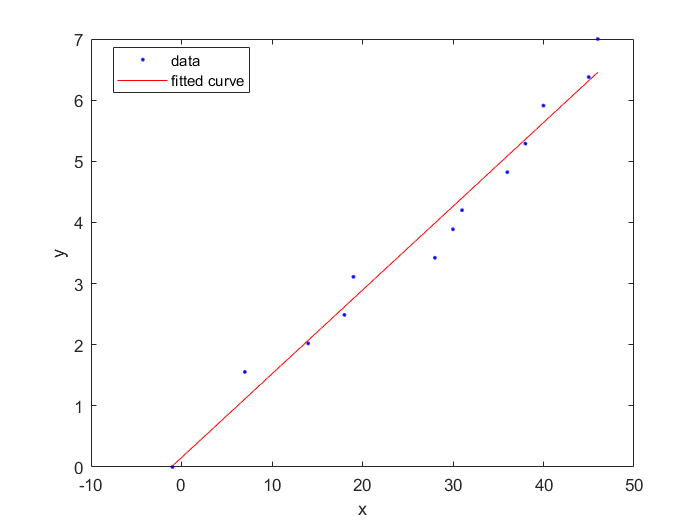

plot(curvefit,I',V')
legend("location",'best')

clear all
close all
load census.mat
[curvefit,gof,output]=fit(cdate,pop,'poly2')

curvefit =      Linear model Poly2:
     curvefit(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =    0.006541  (0.006124, 0.006958)
       p2 =      -23.51  (-25.09, -21.93)
       p3 =   2.113e+04  (1.964e+04, 2.262e+04)

gof = struct with fields:
           sse: 159.0293
       rsquare: 0.9987
           dfe: 18
    adjrsquare: 0.9986
          rmse: 2.9724


output = struct with fields:
        numobs: 21
      numparam: 3
     residuals: [21×1 double]
      Jacobian: [21×3 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


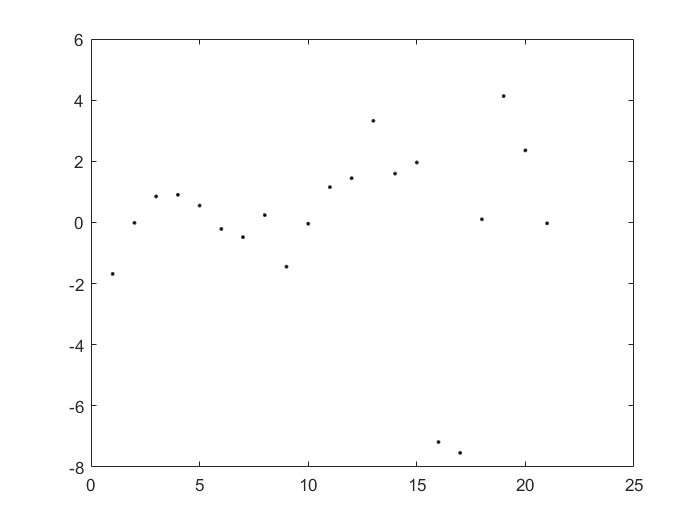

plot(curvefit,cdate,pop)
figure
plot(output.residuals,".k")

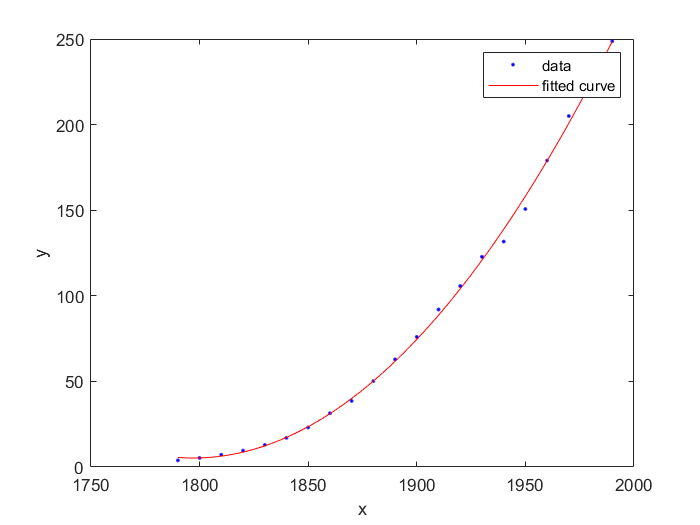

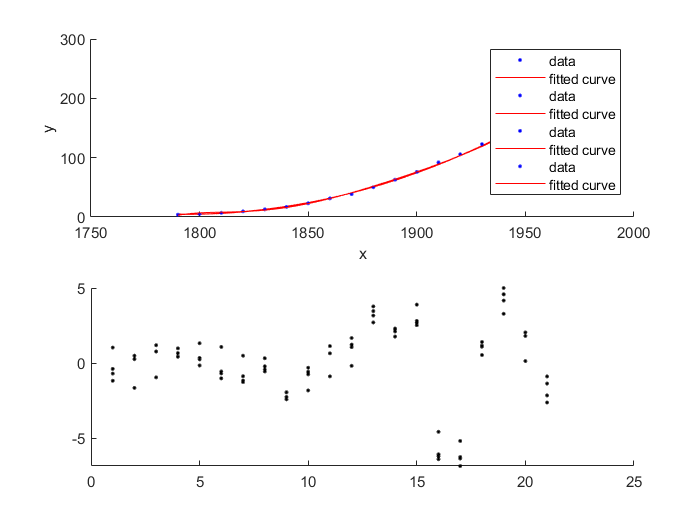

for n=3:6
    subplot(2,1,1)
    hold on
    [curvefit,gof,output]=fit(cdate,pop,"poly"+n,'Normalize','on');
    plot(curvefit,cdate,pop)
    subplot(2,1,2)
    hold on
    
    plot(output.residuals,".k")
end
figure
    [curvefit,gof,output]=fit(cdate,pop,"exp1",'Normalize','on');

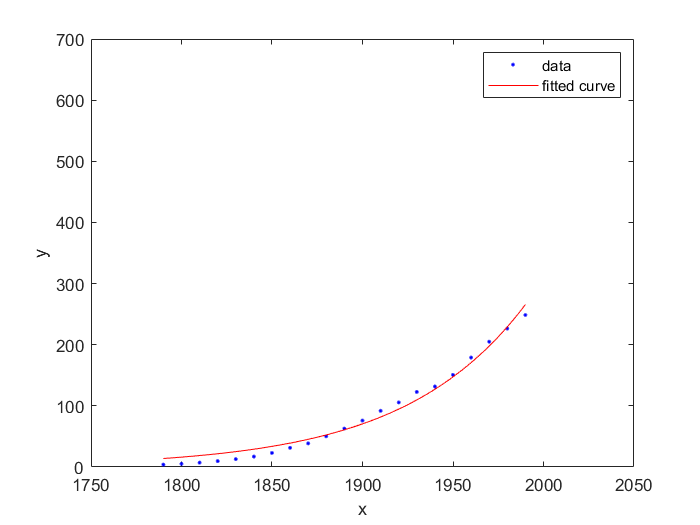

    plot(curvefit,cdate,pop)
    xlim([1750 2050])
    ylim([0 700])

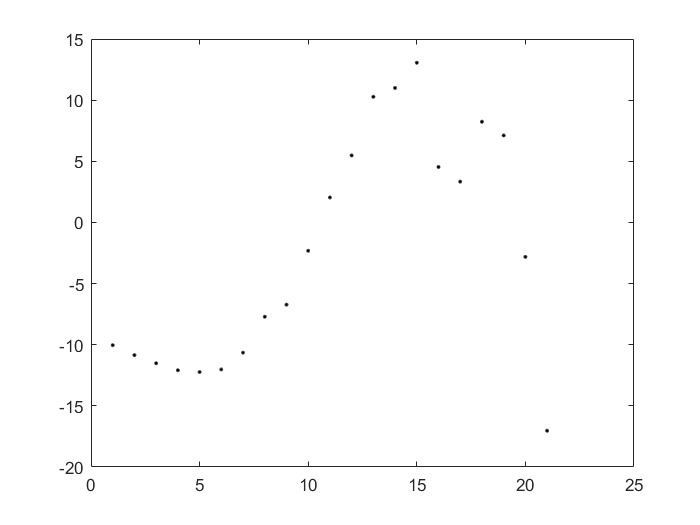

    figure
    plot(output.residuals,".k")